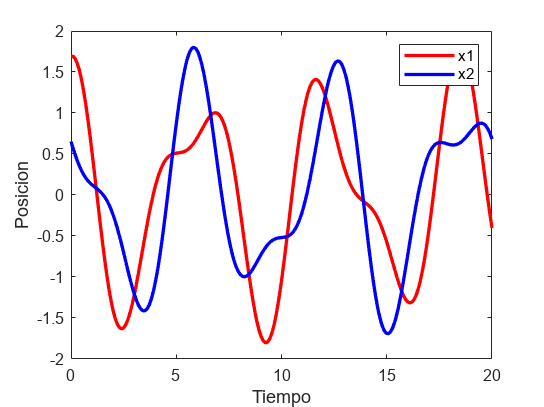

m = 1;    % Masa
k1 = 0.1;   % Constante del primer resorte
k2 = 0.1;   % Constante del segundo resorte

% Matriz A
A = [0          1          0          0;
     -2 * k1/m     0          k2/m       0;
     0          0          0          1;
     k1/m       0         -2 * k2/m      0];

% Condiciones iniciales
x0 = [1; 0; 0; 1];

% Calculo de valores y vectores propios
[V, D] = eig(A);

% Iteracion de la solucion luego de k etapas :
syms t;
X = c(1) * exp(l1 * t) * v1 + c(2) * exp(l2 * t) * v2 + c(3) * exp(l3 * t) * v3 + c(4) * exp(l4 * t) * v4;

% Para la condición inicial proporcionada
c = inv(V) * x0;


% Grafica de la solucion
t = linspace(0,20, 200); % Intervalo de tiempo
x1 = subs(X(1), t); % Posicion x1
x2 = subs(X(3), t); % Posicion x2

plot(t, x1, 'r', 'LineWidth', 2);
hold on;
plot(t, x2, 'b', 'LineWidth', 2);
xlabel('Tiempo');
ylabel('Posicion');
legend('x1', 'x2');

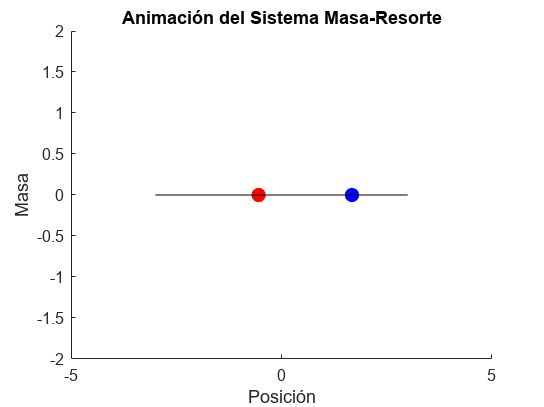



% Definir el tiempo de simulación y el paso de tiempo
t = linspace(0, 20, 200); % Intervalo de tiempo
dt = t(2) - t(1);

% Preparar la figura para la animación
figure;
xlim([-5, 5]); % Límites de x para visualizar bien los movimientos
ylim([-2, 2]); % Límites de y simplemente para tener un buen cuadro de visualización
hold on;
xlabel('Posición');
ylabel('Masa');
title('Animación del Sistema Masa-Resorte');

% Crear objetos gráficos que vamos a actualizar en el bucle
h1 = plot(0, 0, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r'); % Masa 1
h2 = plot(0, 0, 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'b'); % Masa 2
spring1 = line([0,0], [0,0], 'Color', 'k'); % Resorte entre pared y masa 1
spring2 = line([0,0], [0,0], 'Color', 'k'); % Resorte entre las masas
spring3 = line([0,0], [0,0], 'Color', 'k'); % Resorte entre masa 2 y pared derecha

for k = 1:length(t)
    % Calcular la posición en el tiempo k
    x1 = -2+real(c(1) * exp(D(1,1) * t(k)) * V(1,1) + c(2) * exp(D(2,2) * t(k)) * V(1,2) ...
        + c(3) * exp(D(3,3) * t(k)) * V(1,3) + c(4) * exp(D(4,4) * t(k)) * V(1,4));
    x2 = 2+ real(c(1) * exp(D(1,1) * t(k)) * V(3,1) + c(2) * exp(D(2,2) * t(k)) * V(3,2) ...
        + c(3) * exp(D(3,3) * t(k)) * V(3,3) + c(4) * exp(D(4,4) * t(k)) * V(3,4));
    
    % Actualizar la posición de las masas
    set(h1, 'XData', x1, 'YData', 0);
    set(h2, 'XData', x2, 'YData', 0);
    
    % Actualizar la posición de los resortes
    set(spring1, 'XData', [-3, x1], 'YData', [0, 0]);
    set(spring2, 'XData', [x1, x2], 'YData', [0, 0]);
    set(spring3, 'XData', [x2, 3], 'YData', [0, 0]);
    
    drawnow; % Redibujar la figura
    pause(dt); % Pausa entre frames para dar efecto de animación
end